# Análisis de Sistemas Electromagnéticos en Ciencias

### Módulo 4: Tarea 2

### Mauricio Andrés Flores Pérez - A01639917

1.- Utilice la funcion de rgresión lineal para resolver el siguiente problema. La tabla muestra los datos de población de un país a lo largo de los últimos años. 

Obtenga la recta dada por una regresión lineal sobre los datos y utilizando esta diga en que año se espera que este país tenga el doble de población de la que tenía en 2010. Muestre una gráfica superponiendo la función y los datos de la tabla. 

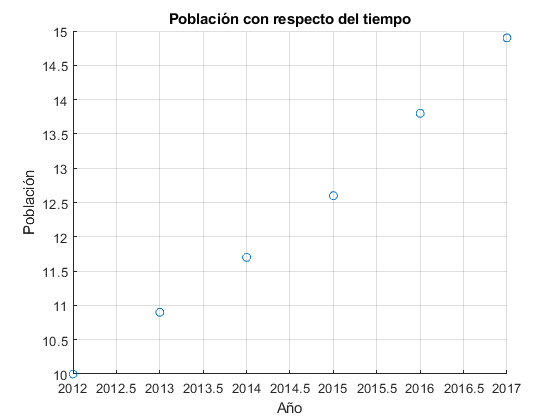

% Colocamos los datos de año y poblacion en dos vectores
% Año = Variable independiente
% Poblacion = variable dependiente
anio = [2012 2013 2014 2015 2016 2017];
poblacion = [10 10.9 11.7 12.6 13.8 14.9];
n = size(anio, 2);

% Graficamos para conocer la tendencia de los datos y confirmar que siguen
% una tendencia lineal
figure(1);
scatter(anio, poblacion);
xlabel('Año'), ylabel('Población'), grid on, title('Población con respecto del tiempo');


% Aplicamos el metodo de regresion lineal por minimos cuadrados
[a0, a1] = linear_regression(anio, poblacion, n);
fprintf("La pendiennte es: %f, la ordenada al origen es: %f\n",a1,a0);

La pendiennte es: 0.974286, la ordenada al origen es: -1950.381905


Para encontrar el año en el que se espera que el país tenga el doble de población que tenía en 2010, primero hay que encontrar por medio del modelo cual es el valor de la población para el año 2010 para posteriormente duplicarlo y saber que número de población estamos buscando. 

anio_2010 = 2010;
poblacion_2010 = a0 + a1*anio_2010;

poblacion_res = poblacion_2010*2;
fprintf("El doble de población que en el año 2010 es: %f\n",poblacion_res);

El doble de población que en el año 2010 es: 15.864762


Ahora solo es necesrio conocer en que año existirá ese número de población. Para esto procedemos con un despeje muy sencillo:


$$y = a_0 + a_1x$$


En donde y es el tamaño de la población en millones, x es el año en el que existe esa población y a0 y a1 son los coeficientes del modelo lineal.


$$x = \frac{y - a_0}{a_1}$$


Con los datos obtenidos anteriormente, obtenemos el año en donde la población será el doble que en el año 2010: 

anio_res = (poblacion_res - a0)/a1;
fprintf("El año es: %f\n",anio_res);

El año es: 2018.141740


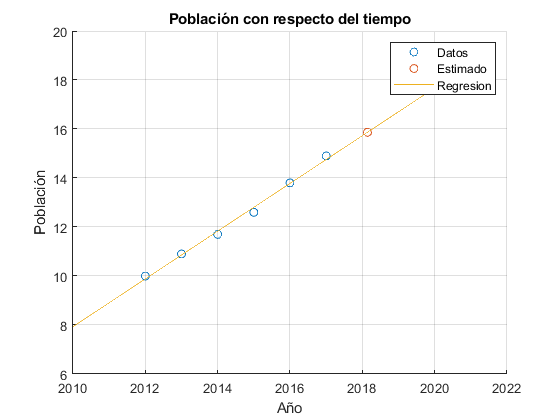


% Graficamos todos los resultados

% Generamos dos vectores con puntos que esten sobre la linea de mejor
% ajuste para poder graficarla
anio_reg = linspace(2010,2021,10000);
poblacion_reg = arrayfun(@(z) (z*a1 + a0),anio_reg);

% Graficamos la linea de mejor ajuste con los datos de la tabla
figure(2);
hold on
scatter(anio,poblacion);
scatter(anio_res, poblacion_res);
plot(anio_reg, poblacion_reg);
xlabel('Año'), ylabel('Población'), grid on, title('Población con respecto del tiempo');
legend('Datos','Estimado', 'Regresion');
hold off

2.- Utilice la funcion de regresión polinomial de grado 2 para ajustar los siguientes datos de la tabla. Haga una gráfica en el mismo archivo, en la que se traslape el polinomio creado en el paso anterior con los datos de la tabla. Recuerde que los datos deben verse como puntos en el plano. Analice el dibujo determinando si la regresión se ajusta o no a los puntos datos. 

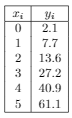

% Colocamos los valores en dos vectores
x = [0 1 2 3 4 5];
y = [2.1 7.7 13.6 27.2 40.9 61.1];
n = size(anio, 2);

% Obtenemos los valores de los coeficientes para la regresion cuadratica
[a0, a1, a2] = cuadratic_regression(x, y, n);

fprintf("a0: %f, a1: %f, a2: %f\n",a0,a1,a2);

a0: 2.478571, a1: 2.359286, a2: 1.860714


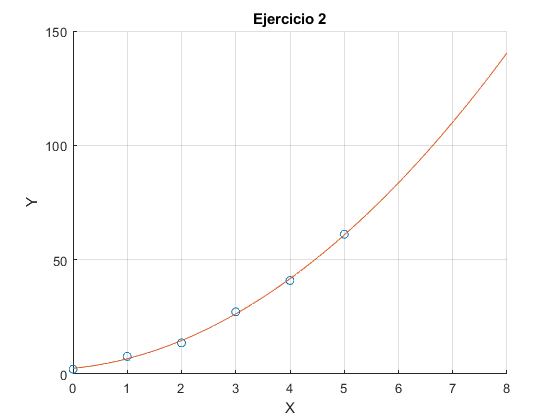


% Creamos un vector con puntos auxiliares para poder observar la funcion
x_reg = linspace(0,8,100);
y_reg = arrayfun(@(z) ((z^2)*a2 + z*a1 + a0),x_reg);

% Graficamos el polinomio junto con los datos para observar que tan bien se
% ajusta
figure(3);
hold on
scatter(x,y);
plot(x_reg, y_reg), xlabel('X'), ylabel('Y'), grid on, title('Ejercicio 2');
hold off

Como se observa en la gráfica de la función, los puntos se ajustan correctamente a un modelo cuadrático, además de que la propia tendencia de los datos parece indicarlo.

**Funciones auxiliares para el método de regresión lineal y el método de regresión cuadrática.**

% Regresion lineal

function [a0, a1] = linear_regression(x, y, n)
    a1 = (n*sum(x.*y)-sum(x)*sum(y))/(n*sum(x.^2)-(sum(x))^2);
    a0 = mean(y) - a1*mean(x);
end

% Regresion cuadratica
function [a0, a1, a2] = cuadratic_regression(x, y, n)
    x_i = sum(x);
    x_2 = sum(x.^2);
    x_3 = sum(x.^3);
    x_4 = sum(x.^4);
    
    res_1 = sum(y);
    res_2 = sum(x.*y);
    res_3 = sum((x.^2).*y);
    
    A = [n x_i x_2; x_i x_2 x_3; x_2 x_3 x_4];
    B = [res_1; res_2; res_3];
    coeficientes = linsolve(A, B);
    a0 = coeficientes(1);
    a1 = coeficientes(2);
    a2 = coeficientes(3);
end